% Task 2b: Brief Analysis of the Given Systems

% Clear the workspace and command window
clear; clc;

%% System 1: G1(s) = 10 / (s^3 + 5.8*s^2 + 8*s + 20)
% Define the transfer function G1(s)
num1 = 10;   % Numerator
den1 = [1 5.8 8 20]; % Denominator coefficients
G1 = tf(num1, den1);

% Analyze System 1
fprintf('System 1: G1(s)\n');

System 1: G1(s)


% Poles
poles_G1 = pole(G1);
fprintf('Poles of G1: \n');

Poles of G1: 


disp(poles_G1);

  -5.0000 + 0.0000i
  -0.4000 + 1.9596i
  -0.4000 - 1.9596i



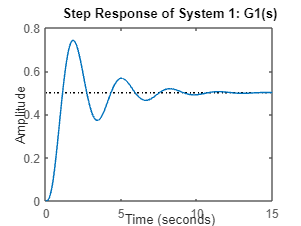


% Step response
figure;
step(G1);
title('Step Response of System 1: G1(s)');

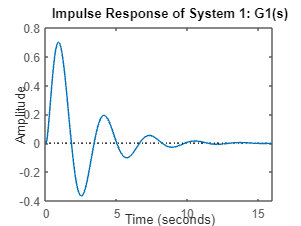


% Impulse response
figure;
impulse(G1);
title('Impulse Response of System 1: G1(s)');

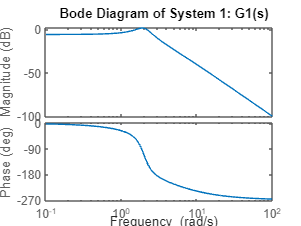


% Bode diagram
figure;
bode(G1);
title('Bode Diagram of System 1: G1(s)');


%% System 2: G2(s) = (0.25 / (s^2 + 1.5*s + 0.5)) * exp(-s)
% Define the transfer function G2(s)
num2 = 0.25;   % Numerator
den2 = [1 1.5 0.5]; % Denominator coefficients
G2 = tf(num2, den2, 'InputDelay', 1);  % InputDelay represents the dead time

% Analyze System 2
fprintf('System 2: G2(s)\n');

System 2: G2(s)


% Poles
poles_G2 = pole(G2);
fprintf('Poles of G2: \n');

Poles of G2: 


disp(poles_G2);

   -1.0000
   -0.5000



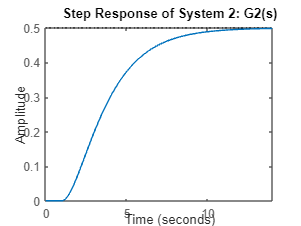


% Step response
figure;
step(G2);
title('Step Response of System 2: G2(s)');

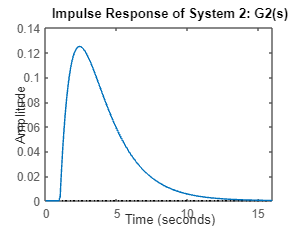


% Impulse response
figure;
impulse(G2);
title('Impulse Response of System 2: G2(s)');

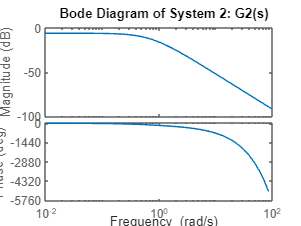


% Bode diagram
figure;
bode(G2);
title('Bode Diagram of System 2: G2(s)');

% Set parameters for dataset generation
%input_type = 'step';  % Choose 'step', 'impulse', or 'prbs'
Ts = 0.01;  % Sampling time (e.g., 0.01 for 100 Hz)
N = 100;  % Number of samples
Sigma = 0.05;  % Standard deviation of noise
seed = 1;  % Random seed for reproducibility

% Generate dataset
[u, y, t] = generate_dataset(G1, 'step', Ts, N, Sigma, seed);

Unrecognized function or variable 'generate_dataset'.